# A example of producing the forward kinematic map.

close
clear
clc
model = UpperLimbModelToolbox();

ans =
     []
ans =
     []


prepare the discretization data

nJoint = 7;
nDiscrete = 6;
joint_min = model.joint_min;
joint_max = model.joint_max;

discretizeArray = zeros(nJoint,nDiscrete);
for iJoint = 1:nJoint
    discreteJoint = linspace(joint_min(iJoint),joint_max(iJoint),nDiscrete);
    discretizeArray(iJoint,:) = discreteJoint;
end

discretizeArray

discretizeArray =    -1.6581   -0.8727   -0.0873    0.6981    1.4835    2.2689
         0    0.6283    1.2566    1.8850    2.5133    3.1416
   -1.5708   -0.8378   -0.1047    0.6283    1.3614    2.0944
         0    0.4538    0.9076    1.3614    1.8151    2.2689
   -1.5708   -0.9425   -0.3142    0.3142    0.9425    1.5708
   -0.1745   -0.0524    0.0698    0.1920    0.3142    0.4363
   -1.2217   -0.7330   -0.2443    0.2443    0.7330    1.2217


Produce the map with forward kinematics.

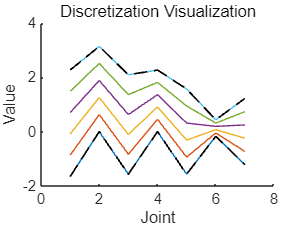

fowardMap = ForwardMap(nJoint, discretizeArray, ...
        "jointMin",joint_min,"jointMax",joint_max)

fowardMap.compute()